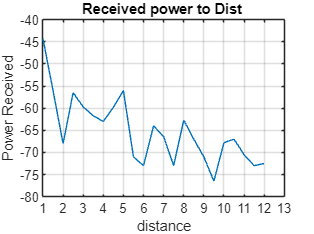

%%metriseis,measurements

powerDBM=[-49 -47.2 -44.3 -56 -68 -56.5 -59.7 -61.7 -63 -59.8 -56 -71 -73 -64 -66.4 -73 -62.7 -67 -71 -76.5 -67.8  -67 -70.5 -73 -72.5];
distanceM=0:0.5:12;

plot(distanceM,powerDBM)
grid on
yticks(-80:5:-40)
xticks(0:1:13)
xtickangle(0)
xlim([1 13])
title("Received power to Dist ")
ylabel("Power Received")
xlabel("distance")

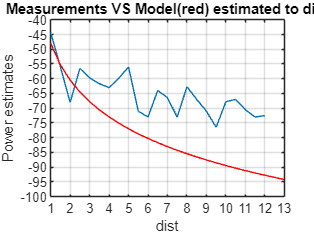



plot(distanceM,powerDBM)
grid on
yticks(-110:5:-40)
xticks(0:1:13)
xtickangle(0)
xlim([1 13])

title("Received power to Dist ")
ylabel("Power Received")
xlabel("distance")
hold on

losses=-1-powerDBM;
losses=losses';

% syntelesths apoleiwn, loss coeff
logDist=log(distanceM);
coeffs=polyfit(distanceM,losses,1);

%kanonikopoihsh,normalization
%arxikh theshs metrishs

distanceM2=distanceM+1;

%model

%%n=coeffs(1)
n=1.8;%% we use 1.8 for simplicity
model=losses(1)+10*n*log(distanceM2);
model = model*(-1);


plot(distanceM2,model,"-r")
title("Measurements VS Model(red) estimated to dist")
xlabel("dist")
ylabel("Power estimates")

hold off

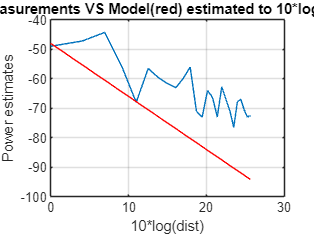


% log dist GRAPHS

plot(10*log(distanceM2),powerDBM)
hold on
grid on
plot(10*log(distanceM2),model,"-r")

title("Measurements VS Model(red) estimated to 10*log(dist)")
xlabel("10*log(dist)")
ylabel("Power estimates")
hold off

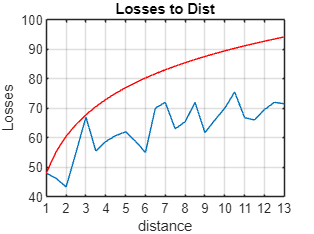



% ME TA LOSSES, with losses


plot(distanceM2,losses)
hold on
grid on

xticks(0:1:13)
xtickangle(0)
xlim([1 13])
title("Losses to Dist")
ylabel("Losses")
xlabel("distance")
plot(distanceM2,(-1)*model,"-r")
hold off

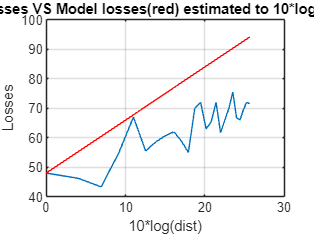






% log dist GRAPHS ME TA LOSSES

plot(10*log(distanceM2),losses)
hold on
grid on
plot(10*log(distanceM2),model*(-1),"-r")

title("Losses VS Model losses(red) estimated to 10*log(dist)")
xlabel("10*log(dist)")
ylabel("Losses")
hold off